clear;
plotting = 1; % 1 for plot, 0 for no plot

sperate_plotting = 1;

A = 1283.0778 % mm^2

A = 1.2831e+03

I = 8.919e-7 % m^4, Near Exact

I = 8.9190e-07

I = 0.00000142318106 % Approximation

I = 1.4232e-06

E = 72 % GPa

E = 72

Al_Tensile = 276 % MPa

Al_Tensile = 276

L = 420 / 1000 % (for 3 and 4 point bending) Span in m

L = 0.4200

a = 150 / 1000 % (for 4 point bending) distance between an outer support and the nearest inner support

a = 0.1500

Load the Files

% Base file path
basePath = 'C:\\Users\\xiaom\\Desktop\\LabCourseLab2\\Data\\';

% Loop over each file
for i = 3:4
    % Generate file name
    fileName = sprintf('Al_%dpt.txt', i);
    filePath = fullfile(basePath, fileName);

    % Read the data, skipping the header
    data = readmatrix(filePath, 'NumHeaderLines', 22);

    % Assign columns to the final variable names using the specified format
    eval(sprintf('Al%d.TM = data(:, 2);', i));
    eval(sprintf('Al%d.MF = -data(:, 3)/1000;', i));
    eval(sprintf('Al%d.MD = data(:, 4);', i));
    eval(sprintf('Al%d.LD = data(:, 5);', i));
    eval(sprintf('Al%d.SG1 = data(:, 6);', i));
    eval(sprintf('Al%d.SG2 = data(:, 7);', i));
    eval(sprintf('Al%d.SG3 = data(:, 8);', i));
    eval(sprintf('Al%d.SG4 = data(:, 9);', i));
end

% Keep rows starting from 13 and beyond for Al3 struct
Al3 = structfun(@(x) x(13:end), Al3, 'UniformOutput', false);

% Keep rows starting from 68 and beyond for Al4 struct
Al4 = structfun(@(x) x(68:end), Al4, 'UniformOutput', false);

Al3.LD = -(Al3.LD - Al3.LD(1));
Al4.LD = -(Al4.LD - Al4.LD(1));

%plot(Al3.LD)
%plot(Al4.LD)

Plotting Load vs Center Deflection

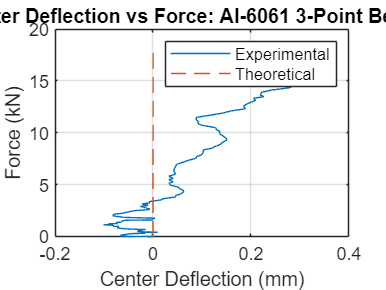

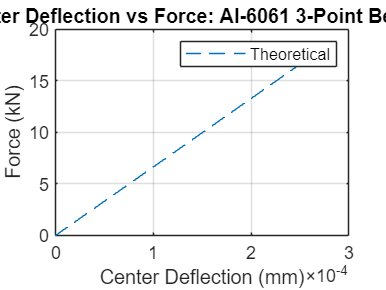

% Convert E from GPa to Pa for consistency in units
E_Pa = E * 1e9; % Convert E from GPa to Pa

% Define the inline function for delta as a function of P (in kN, hence the conversion to N)
delta_3 = @(P) (P * 1e3 * L^3) / (48 * E_Pa * I);
delta_4 = @(P) (P * 1e3 * a * (3*L^2 - 4*a^2)) / (24*E_Pa*I);
%delta_4 = @(P) 185 * P * 1e3 * L^3 / (16464 * E_Pa * I) % Formula derived
%by Chen Yeye

if plotting == 1
    % Plot for Al3: Laser Displacement vs Force
    figure;
    plot(Al3.LD, Al3.MF, 'DisplayName', 'Experimental');
    hold on; % Hold on to add the theoretical line

    % Generate delta values from experimental data
    delta_values = arrayfun(delta_3, Al3.MF); % Calculate delta for each P value

    % Plot theoretical delta vs Force
    plot(delta_values, Al3.MF, '--', 'DisplayName', 'Theoretical');

    % Add title, labels, and legend
    title('Center Deflection vs Force: Al-6061 3-Point Bending');
    xlabel('Center Deflection (mm)');
    ylabel('Force (kN)');
    legend('show');
    grid on;
    hold off; % Release the plot for other plots
    
   
    figure;
    plot(delta_values, Al3.MF, '--', 'DisplayName', 'Theoretical');
    plot(delta_values, Al3.MF, '--', 'DisplayName', 'Theoretical');

    % Add title, labels, and legend
    title('Center Deflection vs Force: Al-6061 3-Point Bending');
    xlabel('Center Deflection (mm)');
    ylabel('Force (kN)');
    legend('show');
    grid on;
    hold off; % Release the plot for other plots
end

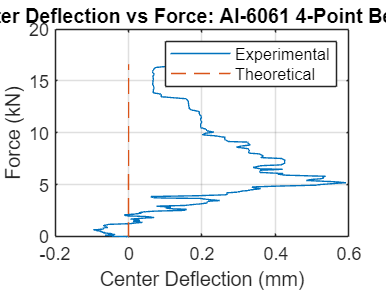

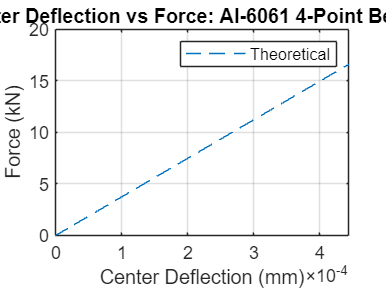



if plotting == 1
    % Plot for Al4: Laser Displacement vs Force
    figure;
    plot(Al4.LD, Al4.MF, 'DisplayName', 'Experimental');
    hold on; % Hold on to add the theoretical line

    % Generate delta values from experimental data
    delta_values = arrayfun(delta_4, Al4.MF); % Calculate delta for each P value

    % Plot theoretical delta vs Force
    plot(delta_values, Al4.MF, '--', 'DisplayName', 'Theoretical');

    % Add title, labels, and legend
    title('Center Deflection vs Force: Al-6061 4-Point Bending');
    xlabel('Center Deflection (mm)');
    ylabel('Force (kN)');
    legend('show');
    grid on;
    hold off; % Release the plot for other plots
    
    
    figure;
    plot(delta_values, Al4.MF, '--', 'DisplayName', 'Theoretical');
    plot(delta_values, Al4.MF, '--', 'DisplayName', 'Theoretical');

    % Add title, labels, and legend
    title('Center Deflection vs Force: Al-6061 4-Point Bending');
    xlabel('Center Deflection (mm)');
    ylabel('Force (kN)');
    legend('show');
    grid on;
    hold off; % Release the plot for other plots
end

Strain Gauges (Seperate Plots)

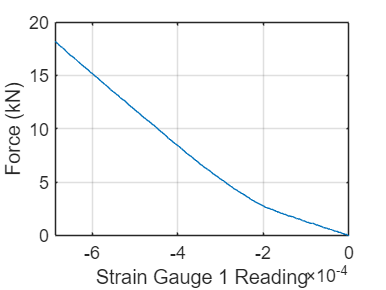

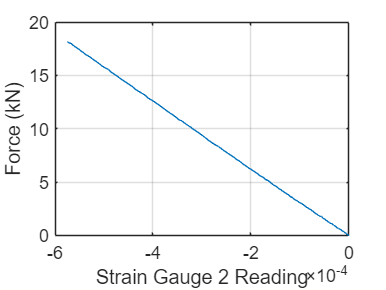

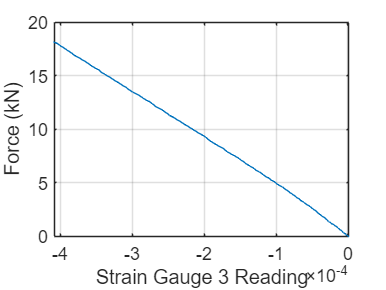

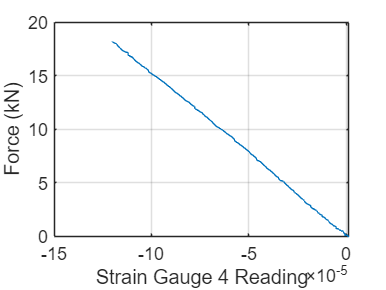

if sperate_plotting == 1
    % Plotting Force vs SG1 for Al3
    figure;
    plot(Al3.SG1, Al3.MF);
    %title('Force vs SG1: Al-6061 3-Point Bending');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 1 Reading');
    grid on;

    % Plotting Force vs SG2 for Al3
    figure;
    plot(Al3.SG2, Al3.MF);
    %title('Force vs SG2: Al-6061 3-Point Bending');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 2 Reading');
    grid on;

    % Plotting Force vs SG3 for Al3
    figure;
    plot(Al3.SG3, Al3.MF);
    %title('Force vs SG3: Al-6061 3-Point Bending');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 3 Reading');
    grid on;

    % Plotting Force vs SG4 for Al3
    figure;
    plot(Al3.SG4, Al3.MF);
    %title('Force vs SG4: Al-6061 3-Point Bending');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 4 Reading');
    grid on;
end

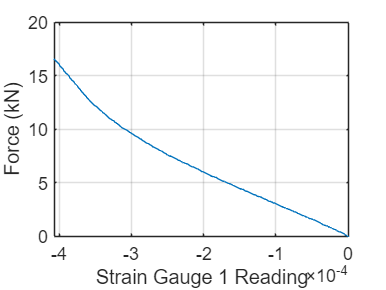

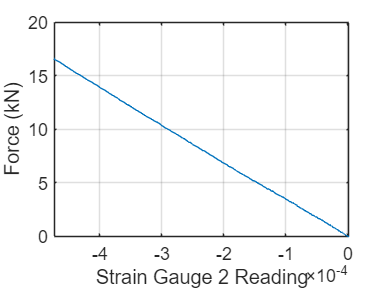

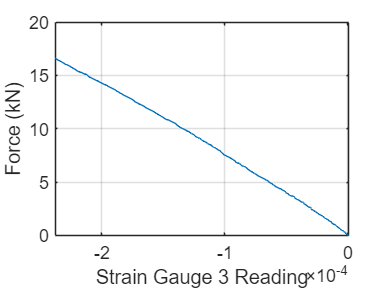

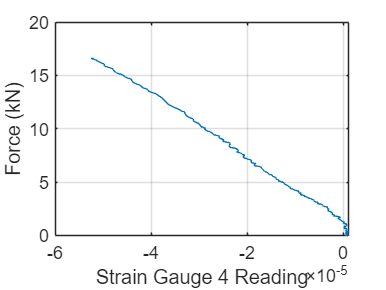


if sperate_plotting == 1
    % Plotting Force vs SG1 for Al4
    figure;
    plot(Al4.SG1, Al4.MF);
    %title('Force vs SG1: Al-6061 4-Point Bending');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 1 Reading');
    grid on;

    % Plotting Force vs SG2 for Al4
    figure;
    plot(Al4.SG2, Al4.MF);
    %title('Force vs SG2: Al-6061 4-Point Bending');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 2 Reading');
    grid on;

    % Plotting Force vs SG3 for Al4
    figure;
    plot(Al4.SG3, Al4.MF);
    %title('Force vs SG3: Al-6061 4-Point Bending');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 3 Reading');
    grid on;

    % Plotting Force vs SG4 for Al4
    figure;
    plot(Al4.SG4, Al4.MF);
    %title('Force vs SG4: Al-6061 4-Point Bending');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 4 Reading');
    grid on;
end

Strain Gauges (Comparison Plots)

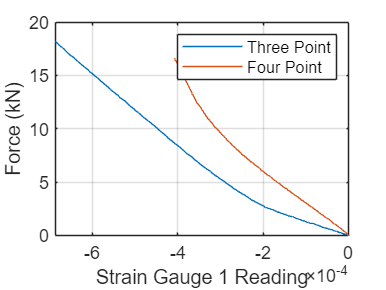

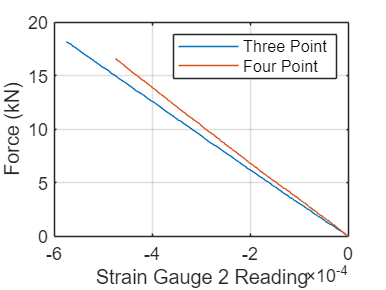

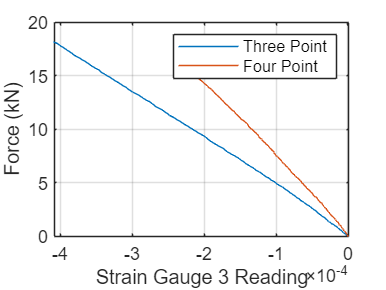

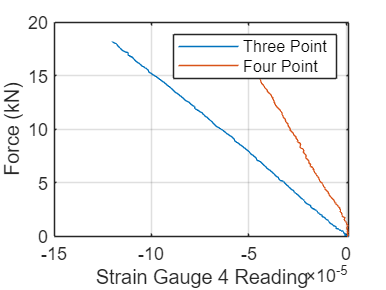

if plotting == 1
    % SG1: Force vs Al3 and Al4 comparison
    figure;
    plot(Al3.SG1, Al3.MF, 'DisplayName', 'Three Point');
    hold on; % Hold to plot Al4 on the same figure
    plot(Al4.SG1, Al4.MF, 'DisplayName', 'Four Point');
    %title('Force vs Strain Gauge 1');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 1 Reading');
    legend('show');
    grid on;
    hold off; % Release the plot

    % SG2: Force vs Al3 and Al4 comparison
    figure;
    plot(Al3.SG2, Al3.MF, 'DisplayName', 'Three Point');
    hold on;
    plot(Al4.SG2, Al4.MF, 'DisplayName', 'Four Point');
    %title('Force vs Strain Gauge 2');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 2 Reading');
    legend('show');
    grid on;
    hold off;

    % SG3: Force vs Al3 and Al4 comparison
    figure;
    plot(Al3.SG3, Al3.MF, 'DisplayName', 'Three Point');
    hold on;
    plot(Al4.SG3, Al4.MF, 'DisplayName', 'Four Point');
    %title('Force vs Strain Gauge 3');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 3 Reading');
    legend('show');
    grid on;
    hold off;

    % SG4: Force vs Al3 and Al4 comparison
    figure;
    plot(Al3.SG4, Al3.MF, 'DisplayName', 'Three Point');
    hold on;
    plot(Al4.SG4, Al4.MF, 'DisplayName', 'Four Point');
    %title('Force vs Strain Gauge 4');
    ylabel('Force (kN)');
    xlabel('Strain Gauge 4 Reading');
    legend('show');
    grid on;
    hold off;
end

Last Question in 8.1.

The purpose of strain gauge 4, which is oriented at 45° to the axis of the beam, is to measure the shear strain on the beam. When a beam is subjected to bending, it experiences both normal stresses (due to bending moments) and shear stresses (due to shear forces). Normal stresses result in the stretching or compression of the material, which is typically measured using strain gauges aligned with or perpendicular to the axis of the beam.

In contrast, shear stresses cause the material to deform in a sliding manner, which is not captured by strain gauges aligned purely axially or transversely. By placing a strain gauge at a 45° angle, the gauge is oriented in such a way that it can respond to the deformation caused by shear stresses. This is due to the fact that at a 45° orientation, the strain gauge is aligned with the maximum shear strain direction under pure shear loading.